# Hw-2 :::  

# Numerical Methods in Electromagnetics

                                                        Mohammadreza Arani                 1401/08/06                              810100511

Problem:                                                          3.9

clear; close all; clc;

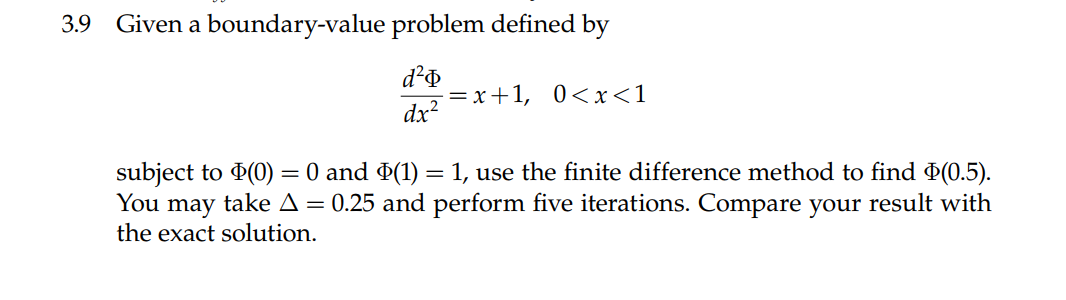

 del_x = 0.25;
    L=1;  % Length of 1-D geometry
    x = 0:del_x:L;
    n = length(x);
    y = zeros(1,n)+1;
    % Boundary conditions:
    y(1,n) = 1 ;
    
    h=del_x;
    B =zeros(n-2,1);
    % The solution is in the paper:
     Afinal = [1 0 0 0 0 ; 1,-2,1,0,0; 0,1,-2,1,0; 0,0,1,-2,1;   0,0,0,0,1 ];
     B(1,1) = 0 ;
     for i=2:length(B)
            B(i,1) = (x(i+1)+1)*h^2; 
     end
     B(n,1)  = 1 ;
    Bfinal = B;

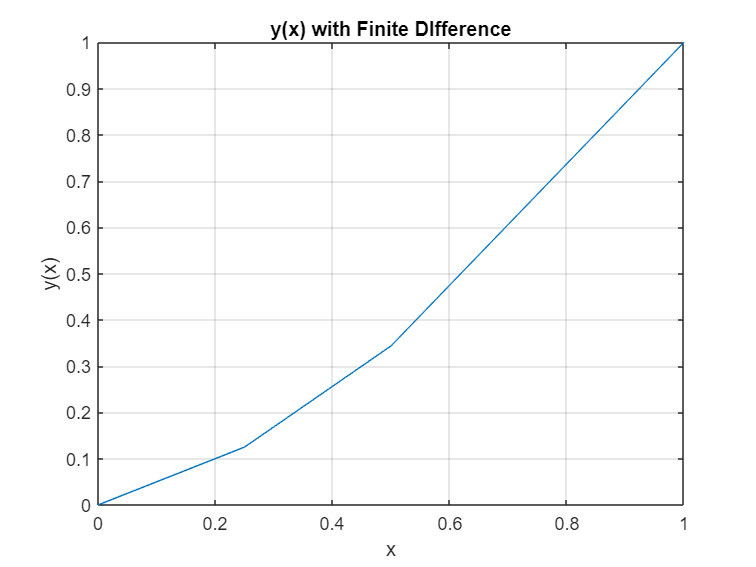



    Yfinal  = mldivide(Afinal,Bfinal) ;
     % Illustrate the figure:
     figure()
     plot(x,[Yfinal])
     title("y(x) with Finite DIfference")
     xlabel("x")
     ylabel("y(x)")
     grid on

disp(Yfinal(3))

    0.3438

